# Tutorial: KiLCA_interface.m

In this tutorial, the basic use of the class KiLCA_interface.m is shown.

## Preparation

Make sure you have an already compiled version of KiLCA on your computer. We recommend to put it into a subfolder called "KiLCA" into your home directory. The newest version by now should then be located in: "'*~/KiLCA/KiLCA-2.4.2*".

- Copy it from */proj/plasma/soft/KiLCA-2.4.2* into your home directory.

- Download from Github: [https://github.com/itpplasma/KiLCA.](https://github.com/itpplasma/KiLCA.) You have to compile it on you own then.

- Otherwise ask Martin or Sergei.

## First Steps

When working in any directory, you can load the class into the MATLAB script with:

addpath('~/KiLCA_interface');

You should specify a working directory for KiLCA:

path = '~/KiLCA_interface/tutorial/';

This uses the existing subfolder "tutorial" as the working directory of KiLCA. Please note that the interface uses the convention that directories are closed with "/".

Now, we can create an object of the class:

kil = KiLCA_interface(path, 'vacuum');

Here we specified the type of run as the second argument: "vacuum". The next thing is to tell the interface, where the executable, blueprints and profiles are located:

kil.EXEC_PATH = '~/KiLCA/KiLCA-2.4.2/exe/KiLCA_Normal_V_2.4.2_MDNO_FPGEN_POLYNOMIAL_Release_64bit';
kil.BLUE_PATH = '~/KiLCA_interface/blueprints/';
kil.PROF_PATH = '~/KiLCA_interface/profiles/';

Please note that the first path leads to a file and not a folder, thus you do not need the "/" in the end. Choose an executable that does not contain the string "EigParam" in it und use "Normal" instead! The blueprint files should be contained in the directory where the interface is located. For the profiles one can use any, the KiLCA_interface folder contains an example which we will use here.

For a fast run, we set the settings to ASDEX (given example profiles are also from ASDEX):

kil.set_ASDEX(0);

The "0" in the argument tells the interface to calculate zero modes (which does not matter because we use a vacuum run).

Now we can write the files and create the directory structure:

kil.write();

If you open your file-explorer you will see some folders and files generated in the working directory "path". Run the code with:

kil.run();

%######################################################
KiLCA start with type = vacuum
KiLCA end with status = 0
%######################################################


Now you should have seen some output in the console. This is generally always created to show when the code starts and when it ends. When the output status is "0", then no error occured and one can continue with post-processing.

By typing in:

kil

kil =   KiLCA_interface with properties:

         EXEC_PATH: '~/KiLCA/KiLCA-2.4.2/exe/KiLCA_Normal_V_2.4.2_MDNO_FPGEN_POLYNOMIAL_Release_64bit'
         BLUE_PATH: '~/KiLCA_interface/blueprints/'
         PROF_PATH: '~/KiLCA_interface/profiles/'
           antenna: [1×1 KiLCA_antenna]
        background: [1×1 KiLCA_background]
           eigmode: [1×1 KiLCA_eigmode]
             modes: [1×1 KiLCA_modes]
            output: [1×1 KiLCA_output]
             zones: {[1×1 KiLCA_zone]  [1×1 KiLCA_zone]  [1×1 KiLCA_zone]}
              path: '~/KiLCA_interface/tutorial/'
       pathofmfile: '/afs/itp.tugraz.at/user/ulbl_p/'
    pathofprofiles: '~/KiLCA_interface/tutorial/profiles/'
         pathofrun: '~/KiLCA_interface/tutorial/vacuum/'
          run_type: 'vacuum'
          run_stat: 0
           run_res: ''
         rdy_torun: 1
       rdy_fromrun: 1
    backgrounddata: [1×1 KiLCA_data_background]
        lineardata: 

you can see the interface object as an console output. You can have a look at the different objects inside the interface to get a feeling about the control of the code. For example:

kil.antenna

ans =   KiLCA_antenna with properties:

      INDICES: [2 3 4 5 6 7 8]
    BLUEPRINT: 'antenna.in'
        READY: 1
           ra: 70
        width: 0
           I0: 4.5000e+12
         flab: [1000 0]
         nmod: 0
     flag_deb: 0
     flag_eig: 0


shows the antenna object which contains all parameters that control the antenna behaviour in the code.

## FLRE Runs & Advanced Controls

Here we show how to make a run using finite larmor radius expansion or FLRE as a plasma model. Additionally a advanced control of input is shown.

We start by initializing an object of the class, this time using flre as a model:

kil = KiLCA_interface(path, 'flre');
kil.BLUE_PATH = '~/KiLCA_interface/blueprints/';
kil.PROF_PATH = '~/KiLCA_interface/profiles/';

Instead of using the predefined ASDEX function, we will set the parameters by hand to show how this works.

### Antenna

First, we set the antenna parameters by using a function which requires the minimum amount of needed parameters (the rest is given by default). The first argument is the position of the antenna and the second one is the amount of modes to calculate.

ra = 70; nmod = 1;
kil.set_antenna(ra, nmod);

Additionally, we want to set the frequency of the perturbations from default (which is 1kHz) to 10kHz. This we do by directly accessing the antenna object in the class:

kil.antenna.flab(1) = 1e4;

Note: the frequency is given as a complex number represented by a 2-element array, so we set the real part previously.

### Background

In the background class, there is also a function to set the minimum amount of required parameters:

Rtor = 170.05; rpl = 67;
kil.set_background(Rtor, rpl);

It takes the big torus radius as the first argument and the plasma radius as the second one.

### Modes

Since we wrote nmod=1 in the antenna object, we need to specify (minimum) the right amount of modes in the modes class. This is done with the set function and cannot be done by direct access because the class needs to check the consistency of both modenumbers specified (this can also be arrays for multiple modes and they should match).

kil.modes.set(5, 2);

The first number is m and the second one n.

### Output

Usually there is not much to change in this class. It contains flags to control the output. For later use we will set to output dispersion data in addition to the standard output:

kil.output.disp = 2;

### Zones

The last step is to define the zones that should be used. Use the following setup:

- minimum radius -> plasma radius: flre zone

- plasma radius -> antenna: vacuum zone

- antenna radius -> wall: vacuum zone

I recommend to start with something like 3cm as the minimum radius and give some space after the antenna to the ideal wall (like 10cm).

Define the positions of the borders:

r = [3, rpl, ra, ra+10];

Next the media in the zones:

m = {'flre', 'vacuum', 'vacuum'};

Finally, the boundaries:

b = {'center', 'interface', 'antenna', 'idealwall'};

Now we can set the zones:

kil.set_zones(r, b, m);

The code should be ready to run:

kil.write();

kil.run();

%######################################################
KiLCA start with type = flre
KiLCA end with status = 0
%######################################################


The next section will show you, how to get the ouput.

## Getting the Output of KiLCA

After you have run the code in the previous section it is time to make some pictures.

### Backgrounddata

Basic KiLCA calculations always create backgrounddata. This is represented by a special class in the interface. You can have a look what's inside by using:

kil.backgrounddata

ans =   KiLCA_data_background with properties:

      path: '~/KiLCA_interface/tutorial/flre//background-data/'
         R: [10275×1 double]
        b0: [10275×2 double]
      b0th: [10275×2 double]
       b0z: [10275×2 double]
      Er_i: [10275×2 double]
       hth: [10275×2 double]
        hz: [10275×2 double]
     j0p_m: [10275×2 double]
     j0s_m: [10275×2 double]
      j0th: [10275×2 double]
    j0th_m: [10275×2 double]
       j0z: [10275×2 double]
     j0z_m: [10275×2 double]
      ne_m: [10275×2 double]
      ne_p: [10275×2 double]
       n_i: [10275×2 double]
      ni_m: [10275×2 double]
      ni_p: [10275×2 double]
       nue: [10275×2 double]
       nui: [10275×2 double]
       q_i: [10275×2 double]
      Te_i: [10275×2 double]
      Te_m: [10275×2 double]
      Ti_i: [10275×2 double]
      Ti_m: [10275×2 double]
     Vpe_m: [10275×2 double]
     Vpe_p: [10275×2 double]
     Vpi_m: [10275×2 double

you should not do this all the time, since it is memory heavy because there are multiple quantities with dimension ~ [1e4, 2] that are read into MATLAB from files. It should be implemented in such a way, that they are only read in if they are needed.

The first column always contains the radius, the second one the quantity itself. You can plot any quantity with:

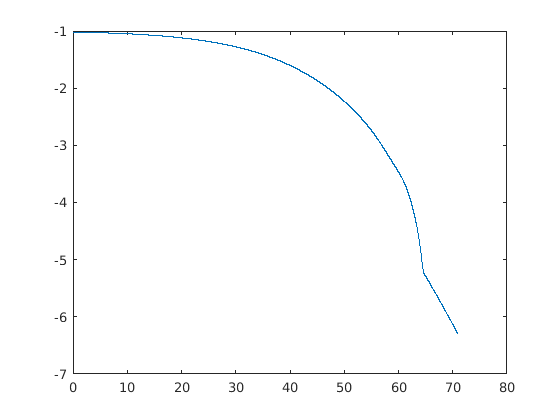

plot(kil.backgrounddata.q_i(:, 1), kil.backgrounddata.q_i(:, 2))

For more convenience there is the function:

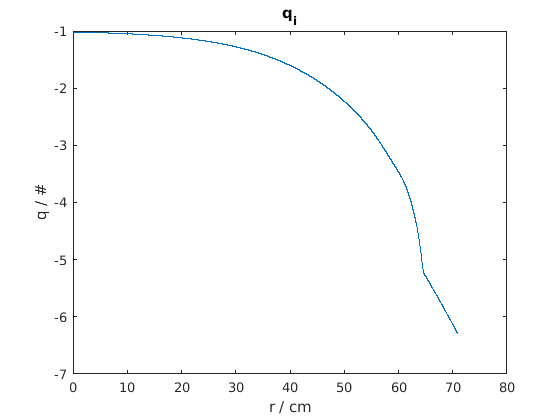

kil.backgrounddata.plot_single('q_i', 'q / #');

That plots any class property specified by its name. The second argument contains a specific y-label, the title and x-label are taken automatically and must be changed from outside if needed. You can also specify plot arguments at the end of the function:

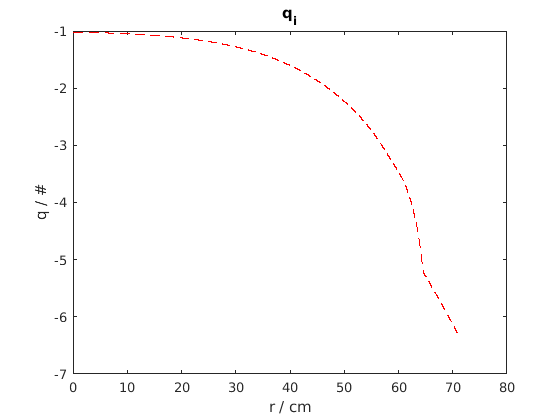

kil.backgrounddata.plot_single('q_i', 'q / #', 'LineStyle', '--', 'Color', 'r');

The most important plot contains the magnetic field which has a special pre-defined function:

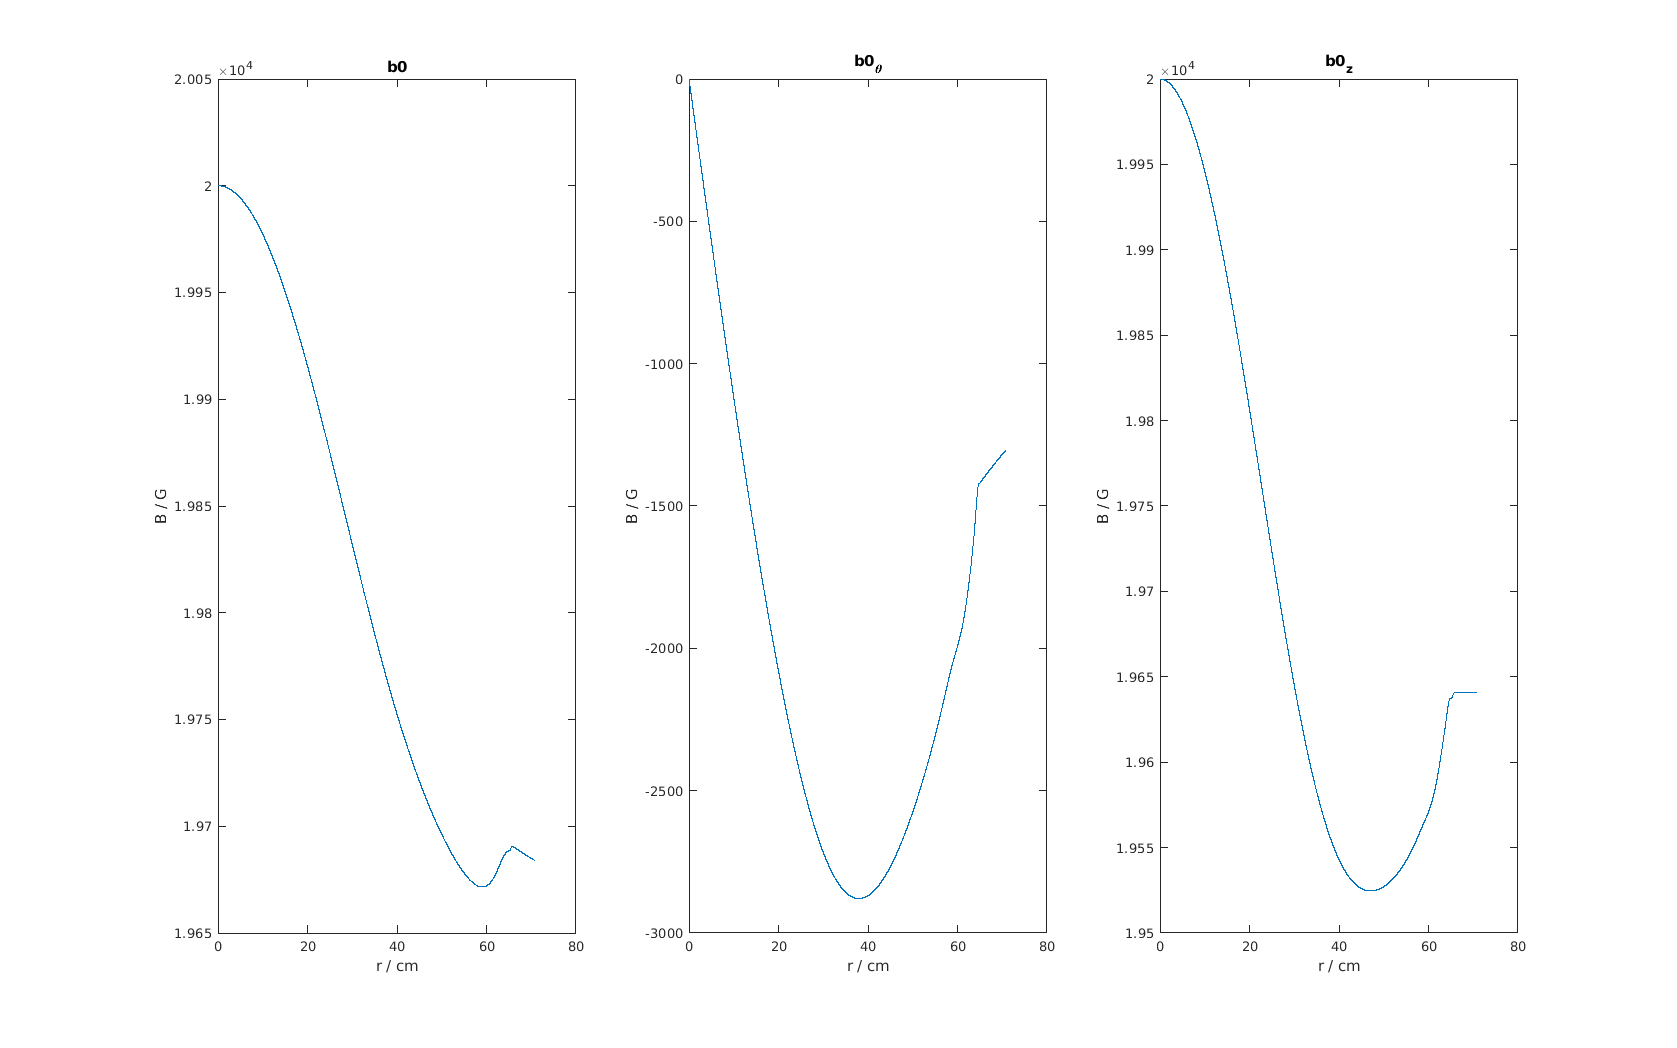

kil.backgrounddata.plotB();

This makes a triple plot including the absolute value, the theta component and the z-component respectively.

### Lineardata

This class contains information about the perturbation: modenumber, position of the resonant surface and E,B profiles (if enabled also poynting flux and other quantitites).

For each mode, one object of this is created. The cell array lineardatacontains  nmod lineardata objects, one for each mode. For example:

kil.lineardata{1}

ans =   KiLCA_data_linear with properties:

       path: '~/KiLCA_interface/tutorial/flre/linear-data/m_5_n_2_flab_[10000,0]/'
       mode: [5 2]
        res: 52.8826
       flab: [10000 0]
       fmov: [1.9359e+04 0]
          R: [5390×1 double]
      Er_Re: [5390×2 double]
      Er_Im: [5390×2 double]
     Er_Abs: [5390×2 double]
     Eth_Re: [5390×2 double]
     Eth_Im: [5390×2 double]
    Eth_Abs: [5390×2 double]
      Ez_Re: [5390×2 double]
      Ez_Im: [5390×2 double]
     Ez_Abs: [5390×2 double]
      Br_Re: [5390×2 double]
      Br_Im: [5390×2 double]
     Br_Abs: [5390×2 double]
     Bth_Re: [5390×2 double]
     Bth_Im: [5390×2 double]
    Bth_Abs: [5390×2 double]
      Bz_Re: [5390×2 double]
      Bz_Im: [5390×2 double]
     Bz_Abs: [5390×2 double]


The modenumbers and position of the resonant surface are given respectively by:

kil.lineardata{1}.mode

ans =      5     2


kil.lineardata{1}.res

ans = 52.8826

There are many different profile quantities (mainly E, B fields with Re, Im and Abs part for all components of the perturbations). Therefore you should stick to use the predefined plot functions:

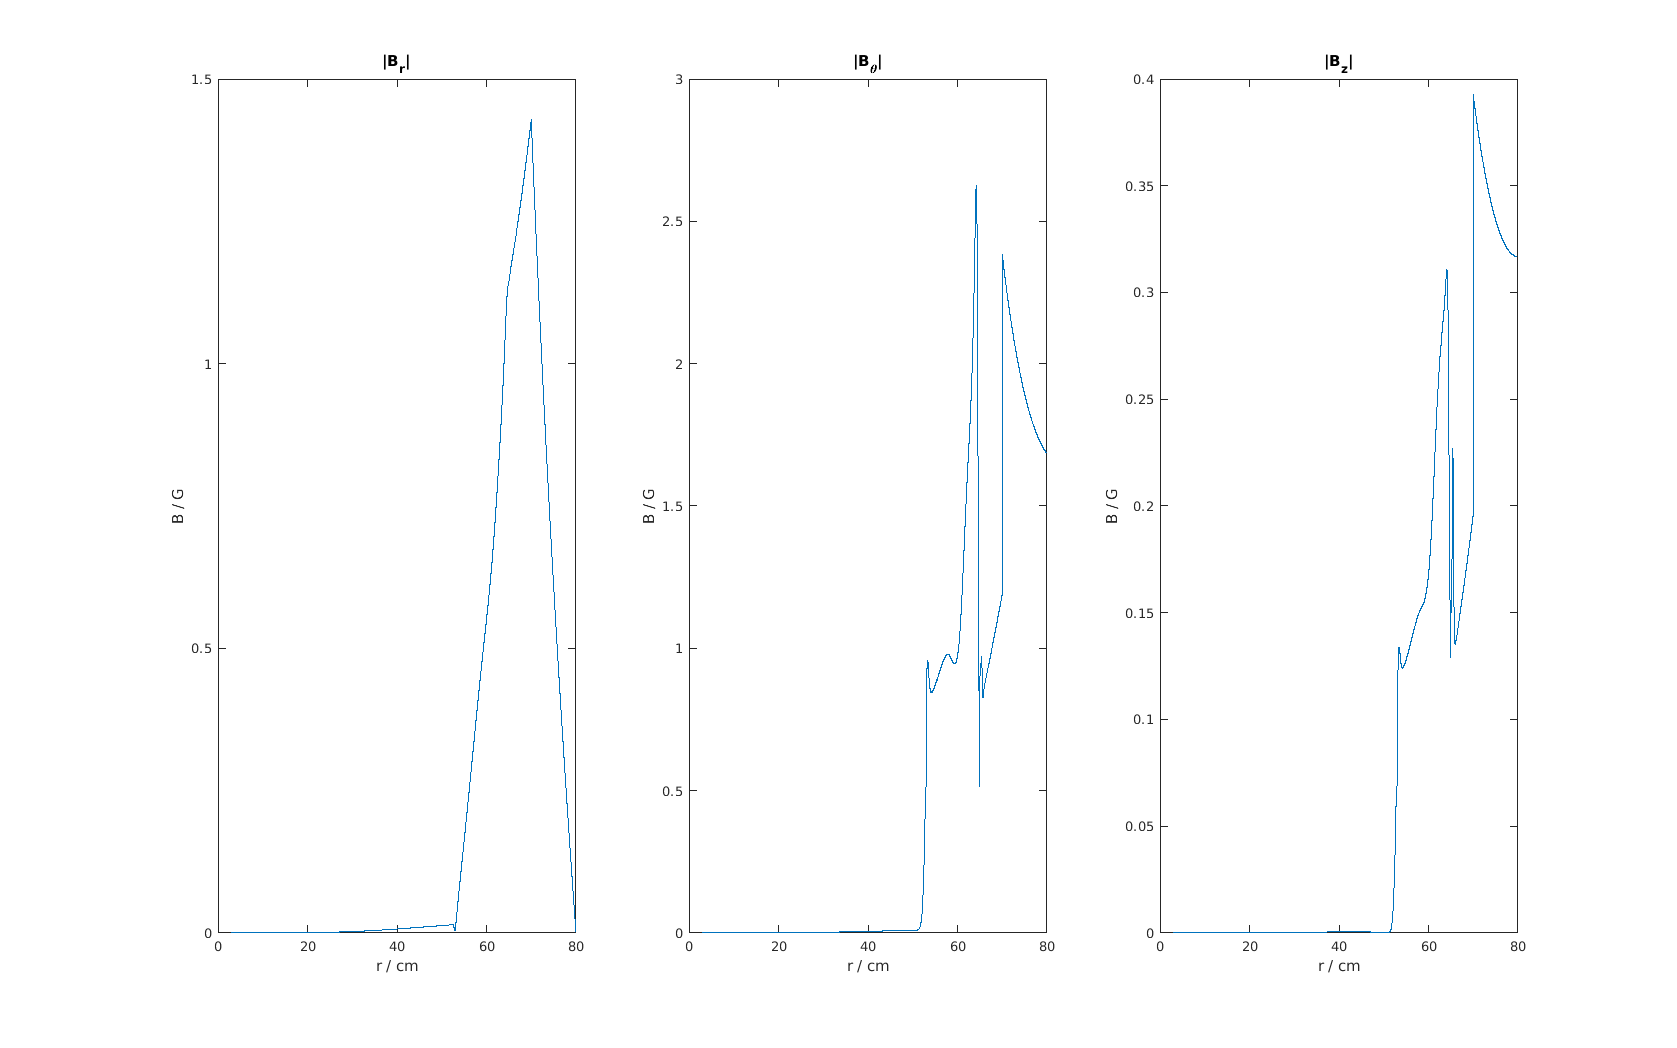

kil.lineardata{1}.plotB();

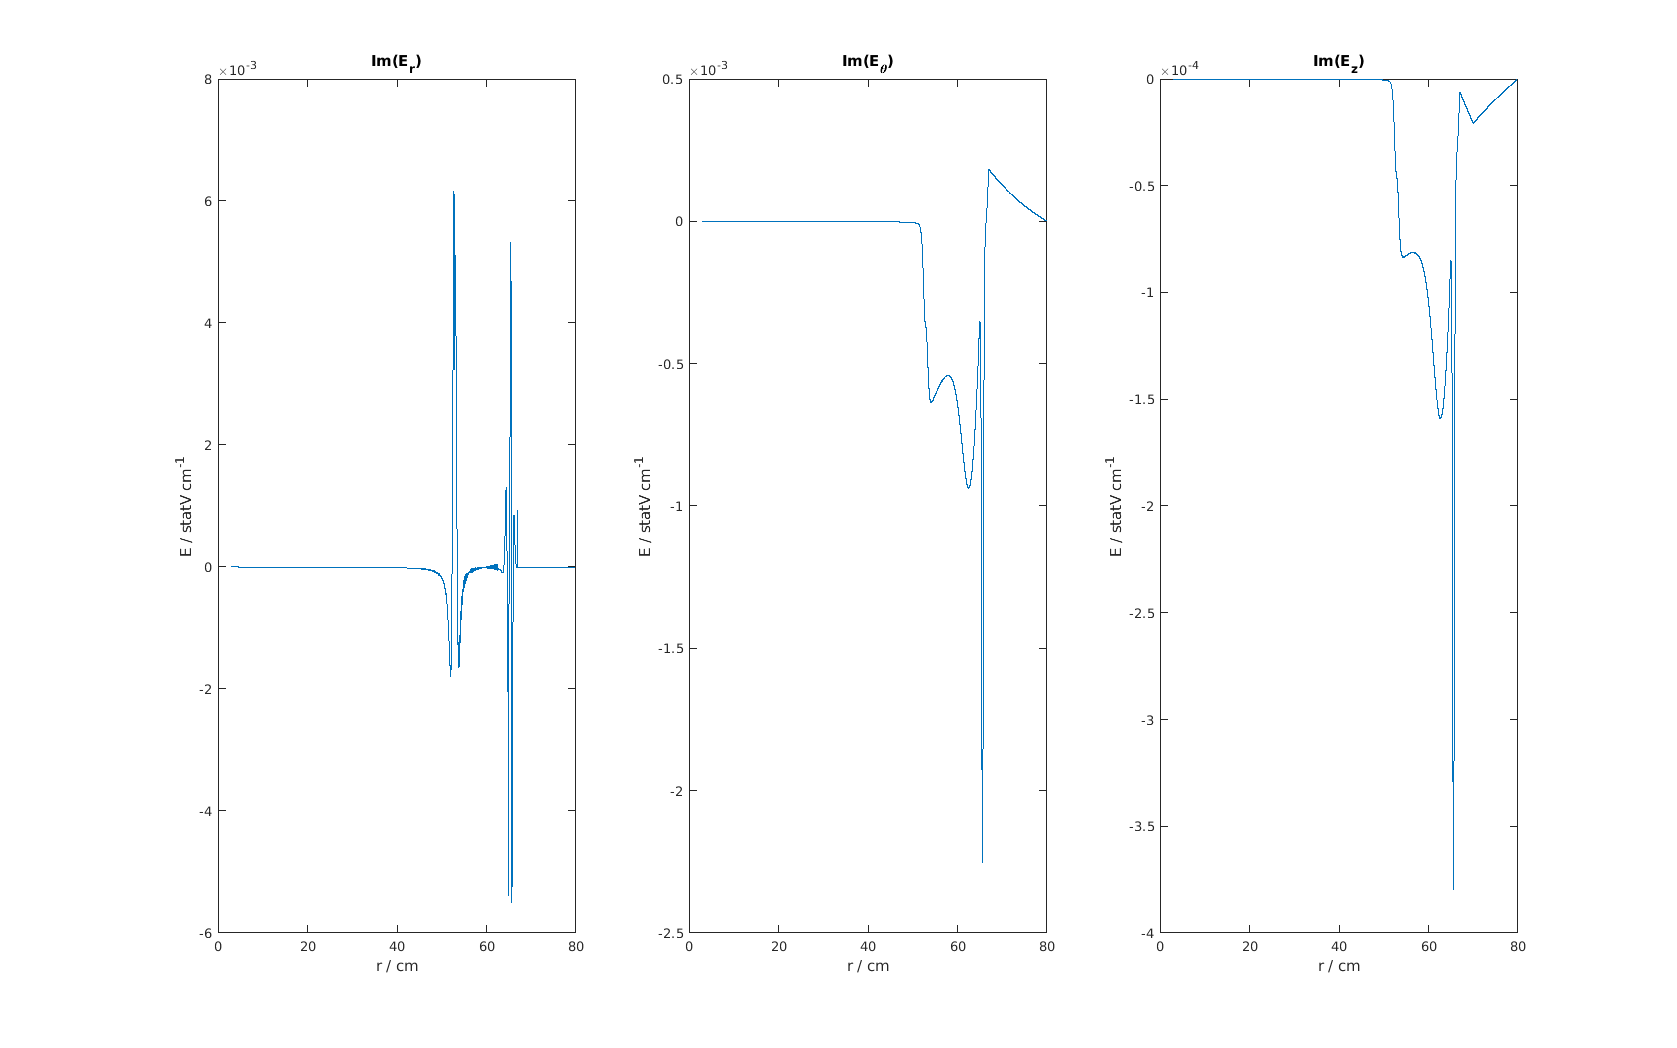

kil.lineardata{1}.plotE('Im');

These take a string as an input which specifies 'Re', 'Im' or 'Abs' (default: empty = 'Abs').

### Dispersiondata

If enabled, this is also created as an output. It works the same way as lineardata. The dispersion curves contained in this class are unfortunately due to KiLCA mixed between different modes that occur. Therefore, the quantities inside are of limited use. If needed you should stick to the predefined plot function, which plots all quantities:

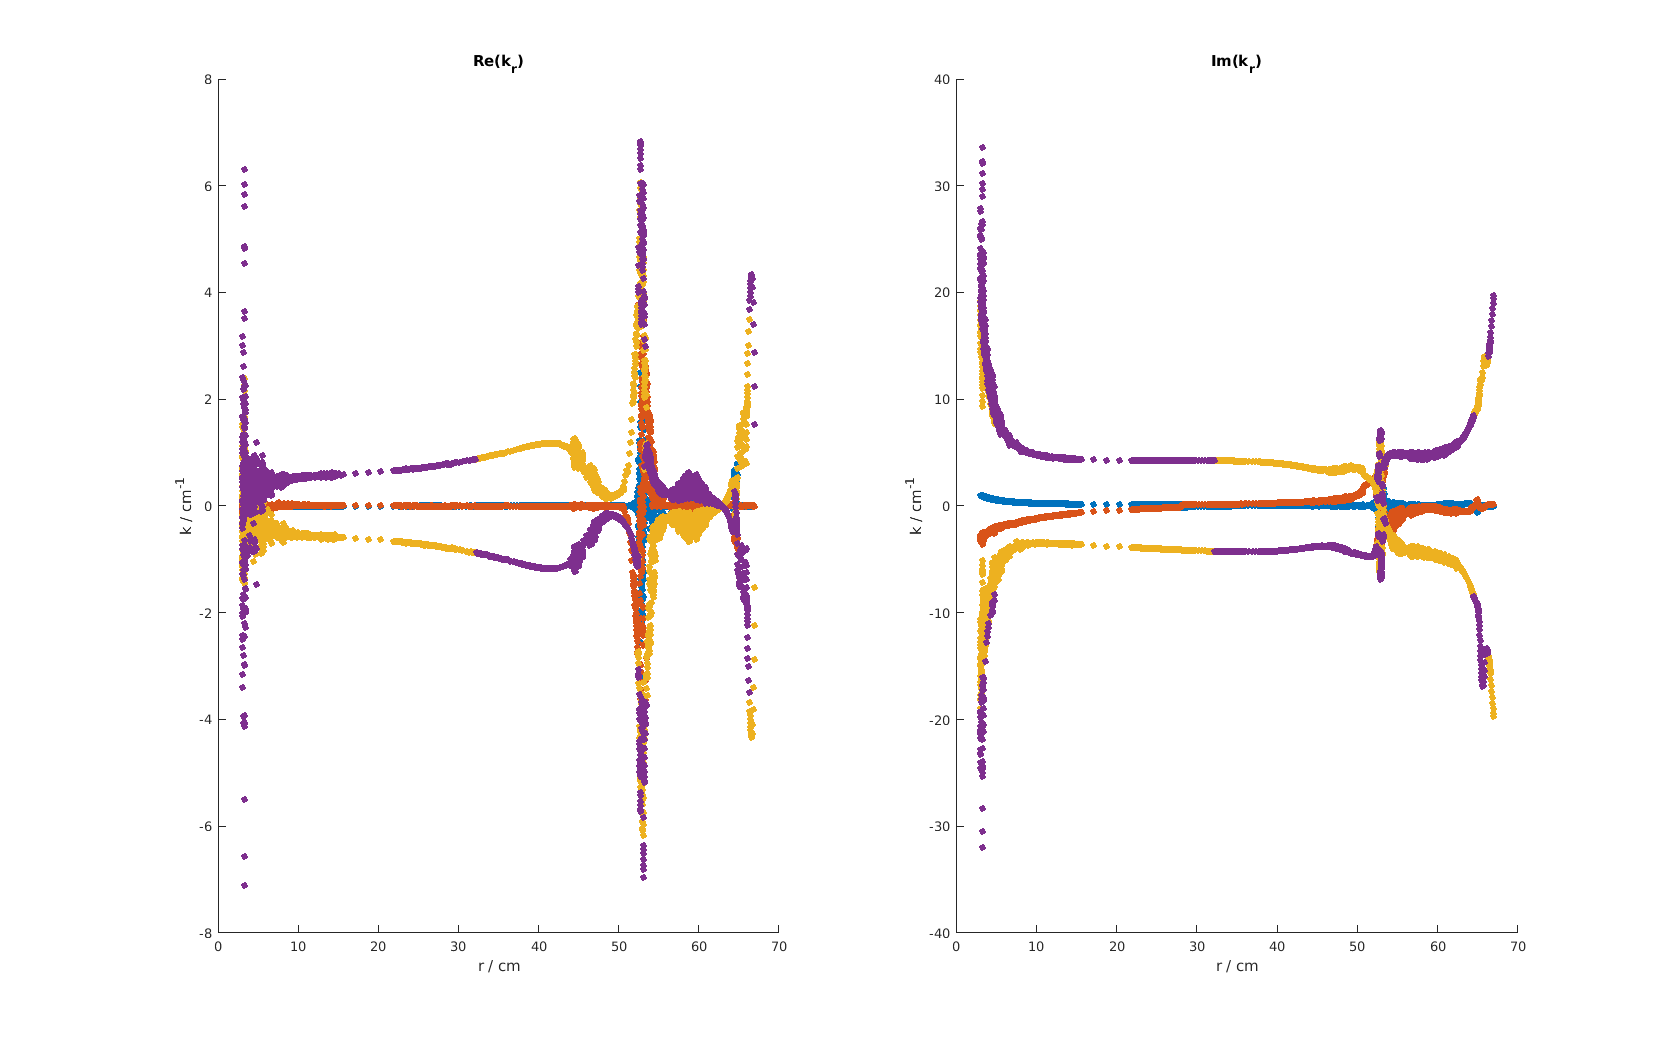

kil.dispersiondata{1}.plot();

## Getting Help

The properties and methods of the classes should explain themself with the comments provided. To access them you can use for example:

% doc KiLCA_interface
% doc KiLCA_antenna
% doc KiLCA_data_linear

These commands will open separate windows with the corresponding documentation for each class. There should be hyperlinks to the corresponding pages for each method inside the class.

You can also use:

help KiLCA_antenna

 classdef KiLCA_antenna
 ##########################################################################
  description of class:
 --------------------------------------------------------------------------
  class containing the information of the antenna in KiLCA.
 ##########################################################################
  properties:
 --------------------------------------------------------------------------
  *) ra, width, I0, freq, nmod, fdeb, feig
  READONLY:
  *) INDICES, BLUEPRINT, READY
 ##########################################################################
  methods:
 --------------------------------------------------------------------------
  *) function obj = antenna(r, n)
  *) function c = plain(obj)
 ##########################################################################

    Reference page for KiLCA_antenna



Or if not sure about the classname of an object:

help(class(kil.output))

 classdef KiLCA_output
 ##########################################################################
  description of class:
 --------------------------------------------------------------------------
  class containing the information of the output in KiLCA.
 
  General run settings: 0 - to skip, 1 - to calculate only,
  2 - to calculate and save to a disk
 ##########################################################################
  properties: (all have defaults!)
 --------------------------------------------------------------------------
  *) backdata, lindata, varquant, disp
  *) flag_deb
  *) curdenspet, abspow, dispow, kinfluxr, poyntfluxr, totfluxr,
     numdenspet, lortorq
  READONLY:
  *) INDICES, BLUEPRINT, READY
 ##########################################################################
  methods:
 --------------------------------------------------------------------------
  *) function obj = KiLCA_output()
  *) function c = plain(obj)
 #######

This provides in-console information about any class, method or property.